读取图片到工作空间，转化为双精度，并显示该图片

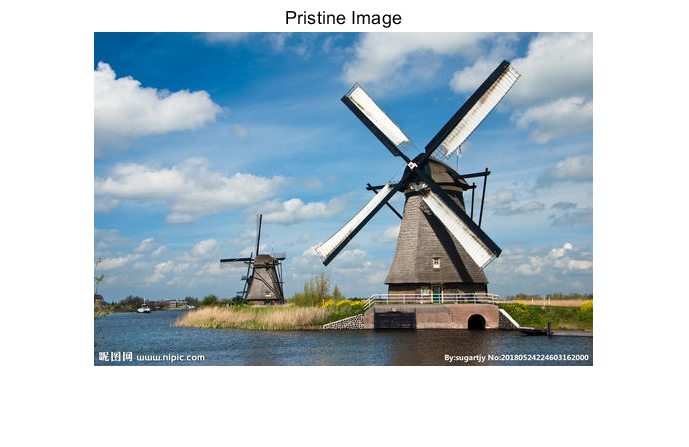

clc;
clear all;
close all;
pristineRGB = imread('picture0.jpg');
pristineRGB = im2double(pristineRGB);
figure(1);
imshow(pristineRGB)
title('Pristine Image')

[pristineR,pristineG,pristineB] = imsplit(pristineRGB);

在图片上加入均值为0，方差为0.01的高斯白噪声，并显示加入噪声后的图片

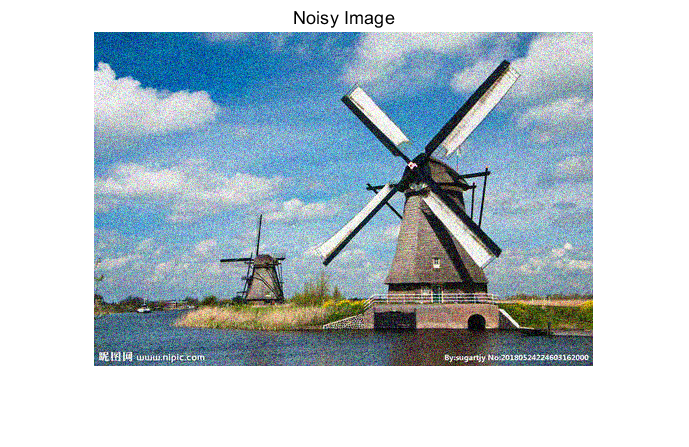

noisyRGB = imnoise(pristineRGB,'gaussian',0,0.01);
figure(2);
imshow(noisyRGB)
title('Noisy Image')

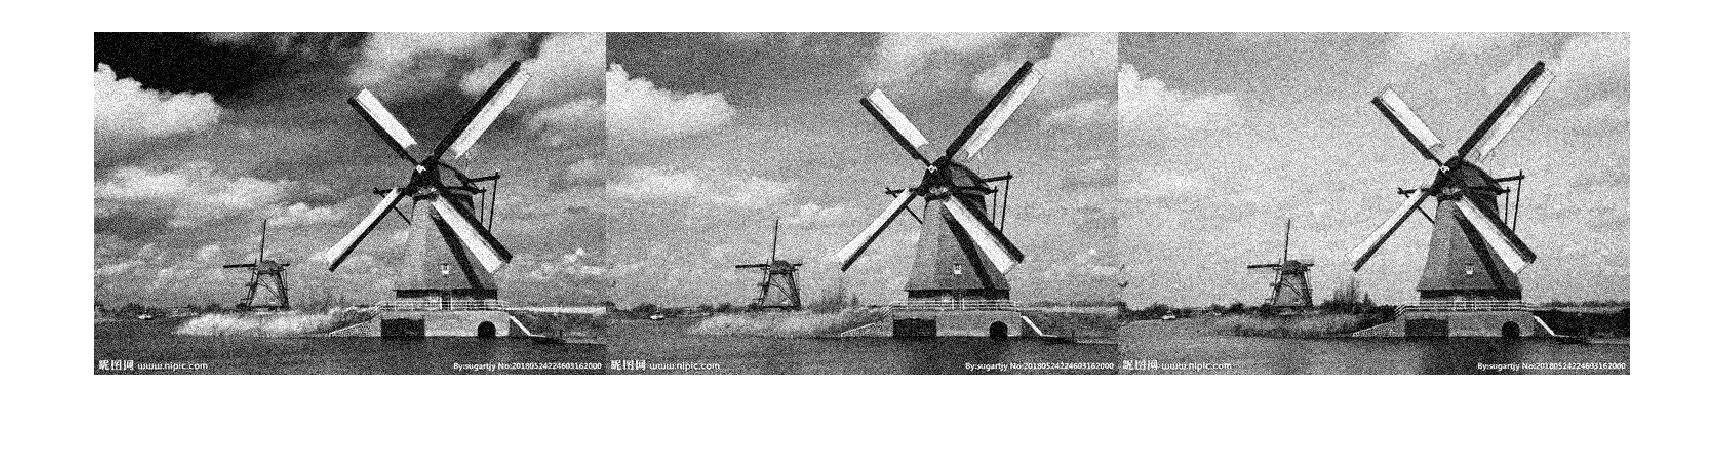

[noisyR,noisyG,noisyB] = imsplit(noisyRGB);
figure(3);
montage({noisyR,noisyG,noisyB},'size',[1,3])

LMS降噪

M = 60;     %滤波器阶数M
mu = 0.0008;  %滤波器的步长
[u,v,w]=size(pristineRGB);
N=u.*v;
k=2;%滤波器阶数
q=0.4;%步长
r=reshape(pristineR,N,1);%reshape按列依次排开
s=reshape(pristineG,N,1);
t=reshape(pristineB,N,1);
rr=reshape(noisyR,N,1);%白噪声
ss=reshape(noisyG,N,1);
tt=reshape(noisyB,N,1);
rrr=rr-r;
sss=ss-s;
ttt=tt-t;

R

figure(4);
subplot(4,1,1);
plot(1:N,r);grid;ylim([-2 2]);
ylabel('幅度');
xlabel('时间');
title('原始信号R');
%% 产生AR模型的噪声
arr=[1,1/2];   %AR模型
v_arr=filter(1,arr,rrr);
% subplot(4,1,2);
% plot(t,v_ar);grid;
% ylabel('幅度');
% xlabel('时间');
% title('AR模型噪声信号');
 
%% 产生MA模型的噪声 是AR模型的相关噪声
mar=[1,-0.8,0.4,-0.2];  %MA模型
v_mar=filter(mar,1,rrr);
subplot(4,1,2);
plot(1:N,v_mar);grid;ylim([-2 2]);
ylabel('幅度');
xlabel('时间');
title('相关噪声信号R');
 
%% 产生期望信号
dnr = r + v_arr;
subplot(4,1,3);
plot(1:N,dnr);grid;ylim([-2 2]);
ylabel('幅度');
xlabel('时间');
title('含噪信号RAR');
 
%% LMS滤波算法
[ylmsr,W,elmsr] =LMSfilter(v_mar,dnr,M,mu);
[ylmsr1,W,elmsr1] =LMSfilter((fliplr(v_mar'))',(fliplr(dnr'))',M,mu); 
%% 绘制去噪后的信号
subplot(4,1,4);
plot(1:N,elmsr);grid;ylim([-2 2]);
ylabel('幅度');
xlabel('时间');
title('去噪后的信号R');
 
er = r-elmsr;%剩余噪声
figure(5);
subplot(2,1,1);
plot(1:N,er);grid;
ylabel('幅度');
xlabel('时间');
title('剩余噪声R');
legend('剩余噪声');
% 一小段三个信号比较
subplot(2,1,2);
time=(115000:115500);
plot(time,elmsr(115000:115500,1 ),'-r',time,er(115000:115500,1),'-g',time,r(115000:115500,1),'-b');
ylabel('幅度');
xlabel('时间');
legend('去噪后的信号R','剩余噪声R','原始信号R');
title('一小段三个信号比较');

G

figure(6);
subplot(4,1,1);
plot(1:N,s);grid;ylim([-2 2]);
ylabel('幅度');
xlabel('时间');
title('原始信号S');
%% 产生AR模型的噪声
ars=[1,1/2];   %AR模型
v_ars=filter(1,ars,sss);
% subplot(4,1,2);
% plot(t,v_ar);grid;
% ylabel('幅度');
% xlabel('时间');
% title('AR模型噪声信号');
 
%% 产生MA模型的噪声 是AR模型的相关噪声
mas=[1,-0.8,0.4,-0.2];  %MA模型
v_mas=filter(mas,1,sss);
subplot(4,1,2);
plot(1:N,v_mas);grid;ylim([-2 2]);
ylabel('幅度');
xlabel('时间');
title('相关噪声信号S');
 
%% 产生期望信号
dns = s + v_ars;
subplot(4,1,3);
plot(1:N,dns);grid;ylim([-2 2]);
ylabel('幅度');
xlabel('时间');
title('含噪信号SAR');
 
%% LMS滤波算法
[ylmss,W,elmss] =LMSfilter(v_mas,dns,M,mu);
[ylmss1,W,elmss1] =LMSfilter((fliplr(v_mas'))',(fliplr(dns'))',M,mu);  
%% 绘制去噪后的语音信号
subplot(4,1,4);
plot(1:N,elmss);grid;ylim([-2 2]);
ylabel('幅度');
xlabel('时间');
title('去噪信号S');
% audiowrite('去噪音频.wav',elms,Fs);%保存去除噪声的音频
 
%%
es = s-elmss;%剩余噪声
figure(7);
subplot(2,1,1);
plot(1:N,es);grid;
ylabel('幅度');
xlabel('时间');
title('剩余噪声S');
 
% 一小段三个信号比较
subplot(2,1,2);
time=(115000:115500);
plot(time,elmss(115000:115500,1 ),'-r',time,es(115000:115500,1),'-g',time,s(115000:115500,1),'-b');
ylabel('幅度');
xlabel('时间');
legend('去噪后的语音信号S','剩余噪声S','原始信号S');
title('一小段三个信号比较');

B

figure(8);
subplot(4,1,1);
plot(1:N,t);grid;ylim([-2 2]);
ylabel('幅度');
xlabel('时间');
title('原始信号T');
%% 产生AR模型的噪声
art=[1,1/2];   %AR模型
v_art=filter(1,art,ttt);
% subplot(4,1,2);
% plot(t,v_ar);grid;
% ylabel('幅度');
% xlabel('时间');
% title('AR模型噪声信号');
 
%% 产生MA模型的噪声 是AR模型的相关噪声
mat=[1,-0.8,0.4,-0.2];  %MA模型
v_mat=filter(mat,1,ttt);
subplot(4,1,2);
plot(1:N,v_mat);grid;ylim([-2 2]);
ylabel('幅度');
xlabel('时间');
title('相关噪声信号T');
 
%% 产生期望信号
dnt = t + v_art;
subplot(4,1,3);
plot(1:N,dnt);grid;ylim([-2 2]);
ylabel('幅度');
xlabel('时间');
title('含噪音信号TAR');
 
%% LMS滤波算法
[ylmst,W,elmst] =LMSfilter(v_mat,dnt,M,mu);
[ylmst1,W,elmst1] =LMSfilter((fliplr(v_mat'))',(fliplr(dnt')'),M,mu);  
%% 绘制去噪后的信号
subplot(4,1,4);
plot(1:N,elmst);grid;ylim([-2 2]);
ylabel('幅度');
xlabel('时间');
title('去噪信号T');
 
%%
et = t-elmst;%剩余噪声
figure(9);
subplot(2,1,1);
plot(1:N,et);grid;
ylabel('幅度');
xlabel('时间');
title('剩余噪声T');
 
% 一小段三个信号比较
subplot(2,1,2);
time=(115000:115500);
plot(time,elmst(115000:115500,1 ),'-r',time,et(115000:115500,1),'-g',time,t(115000:115500,1),'-b');
ylabel('幅度');
xlabel('时间');
legend('去噪后的信号T','剩余噪声T','原始信号T');
title('一小段三个信号比较');

降噪后图片

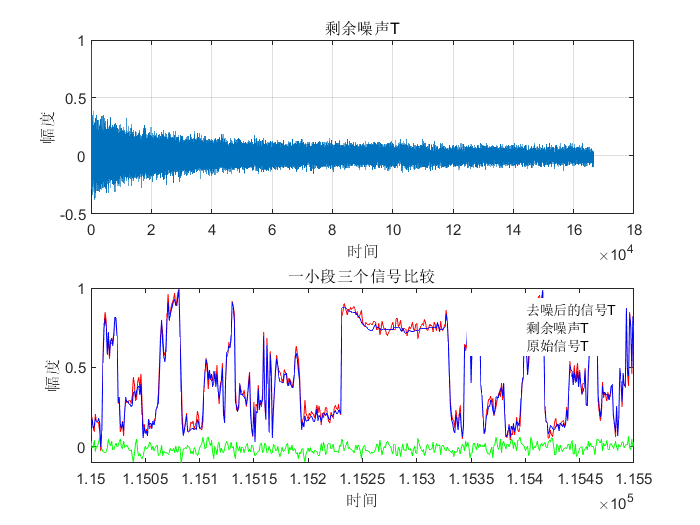

figure(10);
denoisedR=reshape(elmsr,u,v);
denoisedS=reshape(elmss,u,v);
denoisedT=reshape(elmst,u,v);
denoisedRGB=cat(3,denoisedR,denoisedS,denoisedT);
imshow(denoisedRGB)

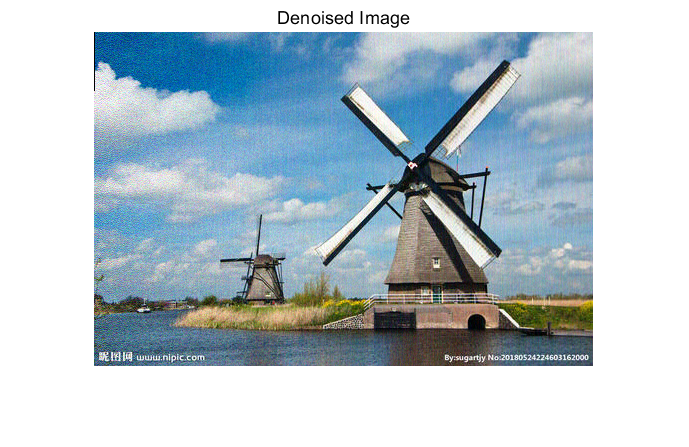

title('Denoised Image');

计算噪声图像和去噪图像的峰值信噪比(PSNR)。PSNR越大，说明噪声的相对信号越小，图像质量越高。

noisyPSNR = psnr(noisyRGB,pristineRGB);
fprintf('\n The PSNR value of the noisy image is %0.4f.',noisyPSNR);


 The PSNR value of the noisy image is 20.1892.

denoisedPSNR = psnr(denoisedRGB,pristineRGB);
fprintf('\n The PSNR value of the denoised image is %0.4f.',denoisedPSNR);


 The PSNR value of the denoised image is 26.1537.

计算去噪和去噪图像的结构相似度(SSIM)指数。SSIM指数接近1表示与参考图像吻合较好，图像质量较高。

noisySSIM = ssim(noisyRGB,pristineRGB);
fprintf('\n The SSIM value of the noisy image is %0.4f.',noisySSIM);


 The SSIM value of the noisy image is 0.6373.

denoisedSSIM = ssim(denoisedRGB,pristineRGB);
fprintf('\n The SSIM value of the denoised image is %0.4f.',denoisedSSIM);


 The SSIM value of the denoised image is 0.8652.

将原R分量前半段噪声截断，R分量颠倒顺序后，计算一次，同样截断前半段，从而降低信噪比。G,B分量亦如法炮制。

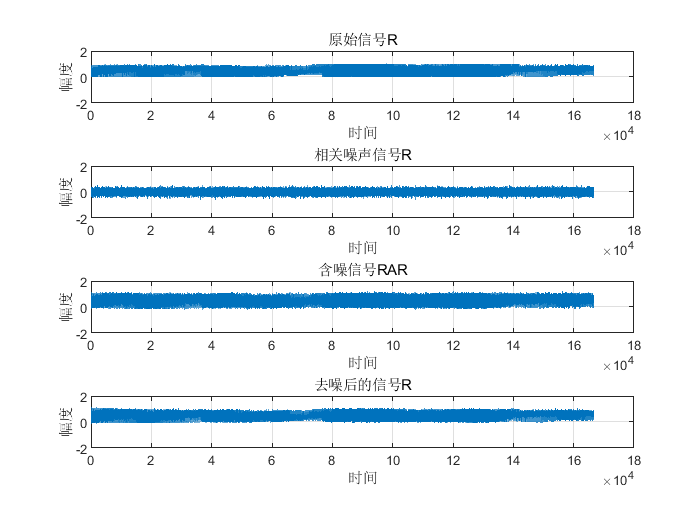

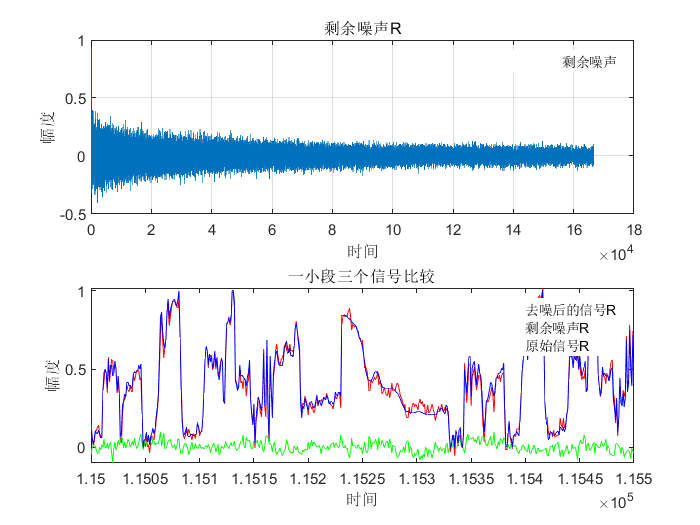

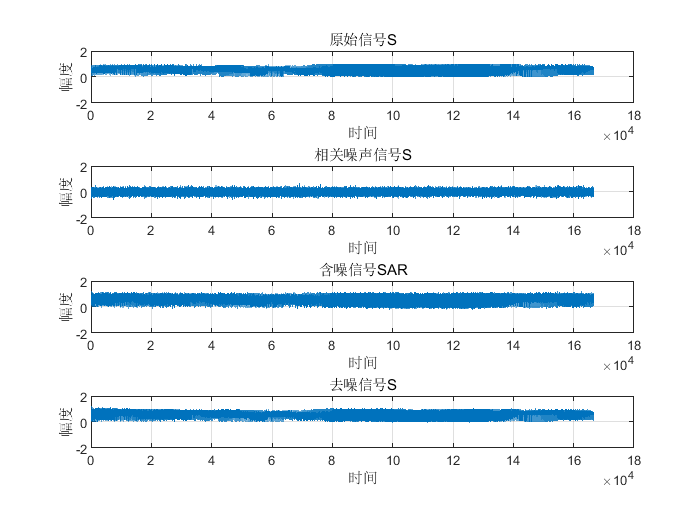

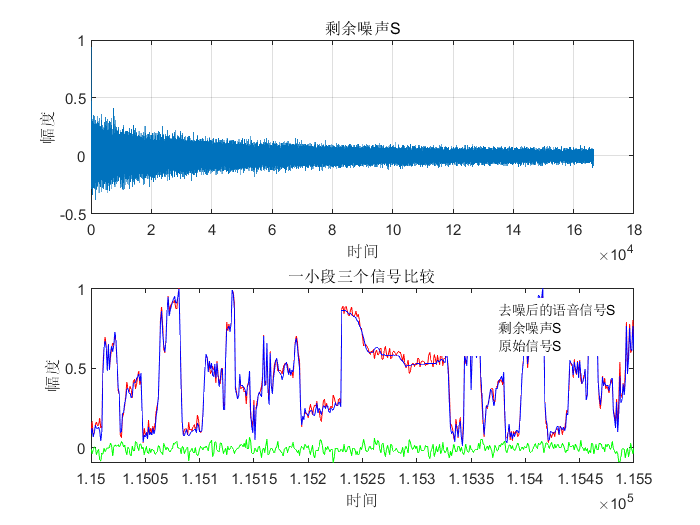

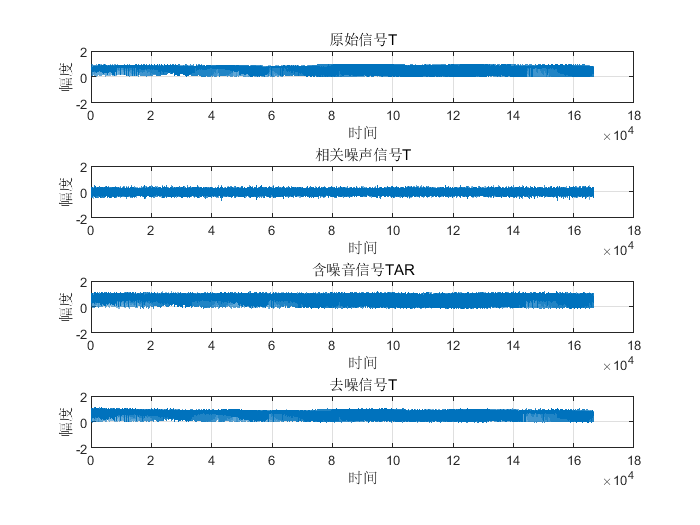

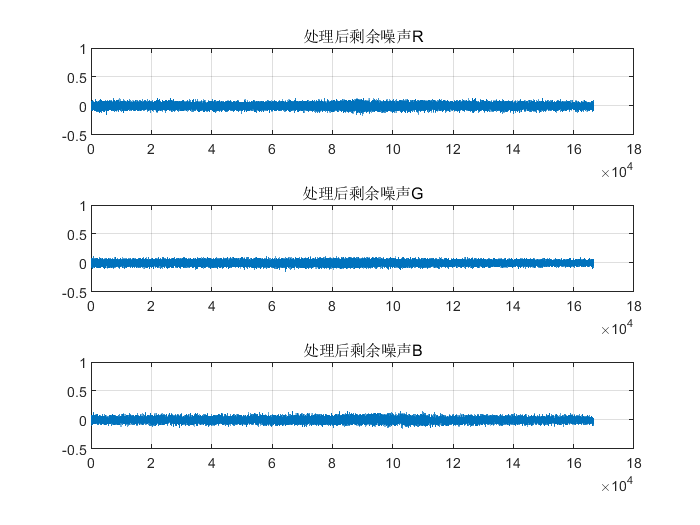

nu=round(N/2);
elmsr11=[fliplr(elmsr1(nu:end,1)'),elmsr(nu+2:end,1)']';
elmss11=[fliplr(elmss1(nu:end,1)'),elmss(nu+2:end,1)']';
elmst11=[fliplr(elmst1(nu:end,1)'),elmst(nu+2:end,1)']';
er1 = r-elmsr11;
es1 = s-elmss11;
et1 = t-elmst11;
figure(11);
subplot(3,1,1);
plot(1:N,er1);grid;
ylim([-0.5 1]);
title('处理后剩余噪声R');
subplot(3,1,2);
plot(1:N,es1);grid;
ylim([-0.5 1]);
title('处理后剩余噪声G');
subplot(3,1,3);
plot(1:N,et1);grid;
ylim([-0.5 1]);
title('处理后剩余噪声B');
figure(12);
denoisedR1=reshape(elmsr11,u,v);
denoisedS1=reshape(elmss11,u,v);
denoisedT1=reshape(elmst11,u,v);
denoisedRGB1=cat(3,denoisedR1,denoisedS1,denoisedT1);
imshow(denoisedRGB1)

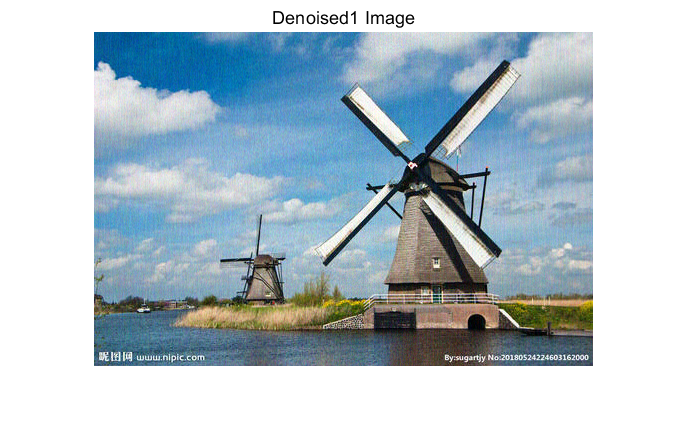

title('Denoised1 Image');

denoisedPSNR1 = psnr(denoisedRGB1,pristineRGB);
fprintf('\n The PSNR value of the denoised image is %0.4f.',denoisedPSNR1);


 The PSNR value of the denoised image is 30.2156.

denoisedSSIM1 = ssim(denoisedRGB1,pristineRGB);
fprintf('\n The SSIM value of the denoised image is %0.4f.',denoisedSSIM1);


 The SSIM value of the denoised image is 0.9225.